# Proceso de identifiación

Importar los datos y guardar el dataset

ident_dataset = readtable('P3.csv')

ident_dataset = 2509×4 table
    Tiempo    Temperatura    TempAjustada    Cmd
    ______    ___________    ____________    ___

     1117        34.94        {'34,94'}      50 
     1118        34.94        {'34,94'}      50 
     1119        34.94        {'34,94'}      50 
     1120        34.94        {'34,94'}      50 
     1121        34.94        {'34,94'}      50 
     1122        34.94        {'34,94'}      50 
     1123        34.94        {'34,94'}      50 
     1124        34.94        {'34,94'}      50 
     1125        34.94        {'34,94'}      50 
     1126           35        {'35,00'}      50 
     1127           35        {'35,00'}      50 
     1128           35        {'35,00'}      50 
     1129        34.94        {'34,94'}      50 
     1130        34.94        {'34,94'}      50 
     1131        34.94        {'34,94'}      50 
 

save("ident_datset.mat","ident_dataset")

Importar dataset. Definimos punto de operación.

load('ident_datset.mat')
data = ident_dataset

data = 2509×4 table
    Tiempo    Temperatura    TempAjustada    Cmd
    ______    ___________    ____________    ___

     1117        34.94        {'34,94'}      50 
     1118        34.94        {'34,94'}      50 
     1119        34.94        {'34,94'}      50 
     1120        34.94        {'34,94'}      50 
     1121        34.94        {'34,94'}      50 
     1122        34.94        {'34,94'}      50 
     1123        34.94        {'34,94'}      50 
     1124        34.94        {'34,94'}      50 
     1125        34.94        {'34,94'}      50 
     1126           35        {'35,00'}      50 
     1127           35        {'35,00'}      50 
     1128           35        {'35,00'}      50 
     1129        34.94        {'34,94'}      50 
     1130        34.94        {'34,94'}      50 
     1131        34.94        {'34,94'}      50 
     1132 

temp_bar = 35;
cmd_bar = 50;

Restamos el punto de operación para hacer las gráficas

temp = data.Temperatura- temp_bar; % 35 
cmd = data.Cmd - cmd_bar; % 50

Graficamos las dos señales

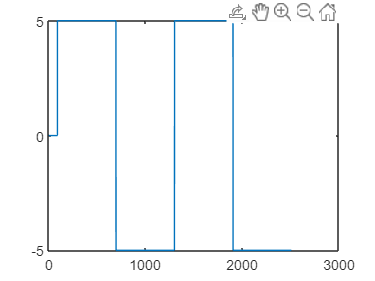

plot(cmd)

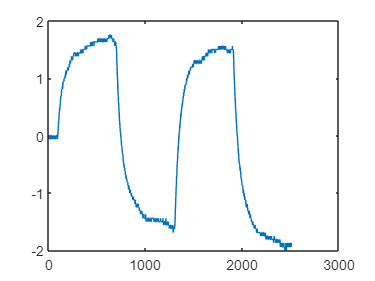

plot(temp)

Obtenemos la función de transferencia con el System Identification Toolbox

tf7

tf7 =
 
  From input "u1" to output "y1":
    0.005457 s + 4.976e-05
  --------------------------
  s^2 + 0.02925 s + 0.000148
 
Name: tf7
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 90.6% (stability enforced) 
FPE: 0.01697, MSE: 0.01692                         


Verificamos la respuesta al paso

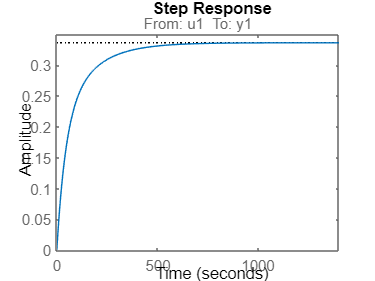

step(tf7)